## 0. Initialize Parameters

L = 1200 % Length of bridge

L = 1200

n = 1200; % Discretize into 1 mm seg.
P = 400; % Total weight of train [N]
x = linspace(0, L, n+1); % x-axis

## 1. SFD, BMD under train loading

% L = 1200 % Length of bridge
% n = 1200; % Discretize into 1 mm seg.
% P = 400; % Total weight of train [N]
% x = linspace(0, L, n+1); % x-axis

x_train = [52 228 392 568 732 908]; % Train Load Locations
P_train = [1 1 1 1 1 1] * P/6;
n_train = 3; % num of train locations
SFDi = zeros(n_train, n+1); % 1 SFD for each train loc.
BMDi = zeros(n_train, n+1); % 1 BMD for each train loc.
% Solve for SFD and BMD with the train at different locations

for i = 1:n_train
    % start location of train
    train_pos = x_train - (n_train - i) * L / n_train

    % sum of moments at A eqn
    real_train_pos = train_pos(train_pos >= 0 & train_pos <= L)
    real_P = P_train(train_pos >= 0 & train_pos <= L)
    moment_A = sum(real_train_pos.*real_P)

    % sum of Fy eqn
    By = moment_A / L
    Ay = sum(real_P) - By

    % construct applied loads
    % w(x)
    SFDi(i, 1) = Ay;
    next_ind = 1;
    for xi = 2:n
        SFDi(i, xi) = SFDi(i, xi-1);
        if next_ind <= length(real_P) & xi >= real_train_pos(next_ind)
            SFDi(i, xi) = SFDi(i, xi) - real_P(next_ind);
            next_ind = next_ind + 1;
        end
    end
    SFDi(i, end) = SFDi(i, end-1) + By
    % plot(x, SFDi)
    
    BMDi(i,:) = cumsum(SFDi(i,:).*(L/n))
    % plot(x, BMDi)
end

train_pos =   -748  -572  -408  -232   -68   108


real_train_pos = 108

real_P = 66.6667

moment_A = 7.2000e+03

By = 6.0000

Ay = 60.6667

SFDi =    60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

BMDi = 1.0e+03 *

    0.0607    0.1213    0.1820    0.2427    0.3033    0.3640    0.4247    0.4853    0.5460    0.6067    0.6673    0.7280    0.7887    0.8493    0.9100    0.9707    1.0313    1.0920    1.1527    1.2133    1.2740    1.3347    1.3953    1.4560    1.5167    1.5773    1.6380    1.6987    1.7593    1.8200    1.8807    1.9413    2.0020    2.0627    2.1233    2.1840    2.2447    2.3053    2.3660    2.4267    2.4873    2.5480    2.6087    2.6693    2.7300    2.7907    2.8513    2.9120    2.9727    3.0333
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

train_pos =   -348  -172    -8   168   332   508


real_train_pos =    168   332   508


real_P =    66.6667   66.6667   66.6667


moment_A = 67200

By = 56

Ay = 144

SFDi =    60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667
  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  

BMDi = 1.0e+04 *

    0.0061    0.0121    0.0182    0.0243    0.0303    0.0364    0.0425    0.0485    0.0546    0.0607    0.0667    0.0728    0.0789    0.0849    0.0910    0.0971    0.1031    0.1092    0.1153    0.1213    0.1274    0.1335    0.1395    0.1456    0.1517    0.1577    0.1638    0.1699    0.1759    0.1820    0.1881    0.1941    0.2002    0.2063    0.2123    0.2184    0.2245    0.2305    0.2366    0.2427    0.2487    0.2548    0.2609    0.2669    0.2730    0.2791    0.2851    0.2912    0.2973    0.3033
    0.0144    0.0288    0.0432    0.0576    0.0720    0.0864    0.1008    0.1152    0.1296    0.1440    0.1584    0.1728    0.1872    0.2016    0.2160    0.2304    0.2448    0.2592    0.2736    0.2880    0.3024    0.3168    0.3312    0.3456    0.3600    0.3744    0.3888    0.4032    0.4176    0.4320    0.4464    0.4608    0.4752    0.4896    0.5040    0.5184    0.5328    0.5472    0.5616    0.5760    0.5904    0.6048    0.6192    0.6336    0.6480    0.6624    0.6768    0.6912 

train_pos =     52   228   392   568   732   908


real_train_pos =     52   228   392   568   732   908


real_P =    66.6667   66.6667   66.6667   66.6667   66.6667   66.6667


moment_A = 1.9200e+05

By = 160.0000

Ay = 240.0000

SFDi =    60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667   60.6667
  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  144.0000  

BMDi = 1.0e+04 *

    0.0061    0.0121    0.0182    0.0243    0.0303    0.0364    0.0425    0.0485    0.0546    0.0607    0.0667    0.0728    0.0789    0.0849    0.0910    0.0971    0.1031    0.1092    0.1153    0.1213    0.1274    0.1335    0.1395    0.1456    0.1517    0.1577    0.1638    0.1699    0.1759    0.1820    0.1881    0.1941    0.2002    0.2063    0.2123    0.2184    0.2245    0.2305    0.2366    0.2427    0.2487    0.2548    0.2609    0.2669    0.2730    0.2791    0.2851    0.2912    0.2973    0.3033
    0.0144    0.0288    0.0432    0.0576    0.0720    0.0864    0.1008    0.1152    0.1296    0.1440    0.1584    0.1728    0.1872    0.2016    0.2160    0.2304    0.2448    0.2592    0.2736    0.2880    0.3024    0.3168    0.3312    0.3456    0.3600    0.3744    0.3888    0.4032    0.4176    0.4320    0.4464    0.4608    0.4752    0.4896    0.5040    0.5184    0.5328    0.5472    0.5616    0.5760    0.5904    0.6048    0.6192    0.6336    0.6480    0.6624    0.6768    0.6912 

SFD = max(abs(SFDi)) % SFD envelope

SFD =   240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000


BMD = max(BMDi) % BMD envelope

BMD = 1.0e+04 *

    0.0240    0.0480    0.0720    0.0960    0.1200    0.1440    0.1680    0.1920    0.2160    0.2400    0.2640    0.2880    0.3120    0.3360    0.3600    0.3840    0.4080    0.4320    0.4560    0.4800    0.5040    0.5280    0.5520    0.5760    0.6000    0.6240    0.6480    0.6720    0.6960    0.7200    0.7440    0.7680    0.7920    0.8160    0.8400    0.8640    0.8880    0.9120    0.9360    0.9600    0.9840    1.0080    1.0320    1.0560    1.0800    1.1040    1.1280    1.1520    1.1760    1.2000


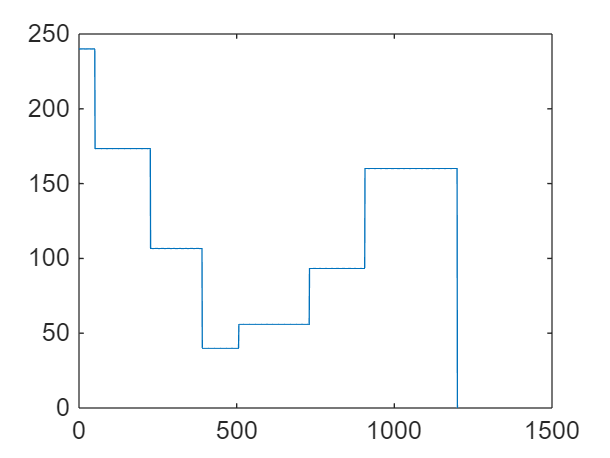


plot(x, SFD)

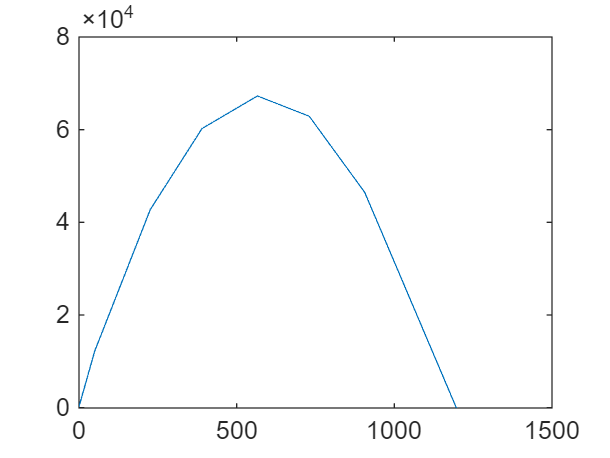

plot(x, BMD)

## 2. Define Bridge Parameters

% = xc, bft, tft,
% param_tf = [0, 100, 1.27;
%         400, 100, 2.54;
%         800, 100, 1.27];  this is me experimenting with changing
%         cross-sections; for now we don't need this but the code is
%         written to work with changing cross-sections as well

% = x_c, b, h
param_tf = [0, 100, 1.27]

param_tf =          0  100.0000    1.2700


param_glue = [0, 5, 1.27];
param_side = [0, 1.27, 75];
param_bot = [0, 80-1.27*2, 1.27];

%x_c Location, x, of cross-section change
%bft Top Flange Width
%tft Top Flange Thickness

% % Extracting user input assuming linear relationship
% bft = interp1(param(:,1), param(:,2), x)
% tft = interp1(param(:,1), param(:,3), x)

btf = zeros(1, n+1);
ttf = zeros(1, n+1);
bglue = zeros(1, n+1);
hglue = zeros(1, n+1);
bside = zeros(1, n+1);
hside = zeros(1, n+1);
bbot = zeros(1, n+1);
hbot = zeros(1, n+1);

btf(1,1) = param_tf(1,2);
ttf(1,1) = param_tf(1,3);
bglue(1,1) = param_glue(1,2);
hglue(1,1) = param_glue(1,3);
bside(1,1) = param_side(1,2);
hside(1,1) = param_side(1,3);
bbot(1,1) = param_bot(1,2);
hbot(1,1) = param_bot(1,3);

next_ind_tf = 2;
next_ind_glue = 2;
next_ind_side = 2;
next_ind_bot = 2;
for i = 2 : n+1
    btf(1, i) = btf(1, i-1);
    ttf(1, i) = ttf(1, i-1);
    bglue(1, i) = bglue(1, i-1);
    hglue(1, i) = hglue(1, i-1);
    bside(1, i) = bside(1, i-1);
    hside(1, i) = hside(1, i-1);
    bbot(1, i) = bbot(1, i-1);
    hbot(1, i) = hbot(1, i-1);

    if next_ind_tf <= length(param_tf(:,1)) & i >= param_tf(next_ind_tf, 1)
        btf(1, i) = param_tf(next_ind_tf, 2);
        ttf(1, i) = param_tf(next_ind_tf, 3);
        next_ind_tf = next_ind_tf + 1;
    end
    if next_ind_glue <= length(param_glue(:,1)) & i >= param_glue(next_ind_glue, 1)
        bglue(1, i) = param_glue(next_ind_glue, 2);
        hglue(1, i) = param_glue(next_ind_glue, 3);
        next_ind_glue = next_ind_glue + 1;
    end
    if next_ind_side <= length(param_side(:,1)) & i >= param_side(next_ind_side, 1)
        bside(1, i) = param_side(next_ind_side, 2);
        hside(1, i) = param_side(next_ind_side, 3);
        next_ind_side = next_ind_side + 1;
    end
    if next_ind_bot <= length(param_bot(:,1)) & i >= param_bot(next_ind_bot, 1)
        bbot(1, i) = param_bot(next_ind_bot, 2);
        hbot(1, i) = param_bot(next_ind_bot, 3);
        next_ind_bot = next_ind_bot + 1;
    end
end

btf

btf =    100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100


ttf

ttf =     1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700


bglue

bglue =      5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5


hglue

hglue =     1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700


bside

bside =     1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700


hside

hside =     75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75


bbot

bbot =    77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600


hbot

hbot =     1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700


## 3. Calculate Sectional Properties

% % ybar. location of centroidal axis from the bottom
% ybar =
% ybot =
% ytop =
% % I
% I =
% % Q at centroidal axes
% Qcent =
% % Q at glue location
% Qglue =

## 4. Calculate Applied Stress

% S_top =
% S_bot =
% T_cent =
% T_glue =

## 5. Material and Thin Plate Buckling Capacities

% E = 4000;
% mu = 0.2;
% S_tens =
% S_comp =
% T_max =
% T_gmax =
% S_buck1 =
% S_buck2 =
% S_buck3 =
% T_buck =

## 6. FOS

% FOS_tens =
% FOS_comp =
% FOS_shear =
% FOS_glue =
% FOS_buck1 =
% FOS_buck2 =
% FOS_buck3 =
% FOS_buckV =

## 7. Min FOS and the failure load Pfail

% minFOS =
% Pf =

## 8. Vfail and Mfail

% Mf_tens =
% Mf_comp =
% Vf_shear =
% Vf_glue =
% Mf_buck1 =
% Mf_buck2 =
% Mf_buck3 =
% Vf_buckV =

## 9. Output plots of Vfail and Mfail

% subplot(2,3,1)
% hold on; grid on; grid minor;
% plot(x, Vf_shear, 'r')
% plot(x, -Vf_shear.* SFD, 'r')
% plot(x, SFDi, 'k');
% plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Matboard Shear Failure')
% xlabel('Distance along bridge (mm)')
% ylabel('Shear Force (N)')
% 
